# **Matlab案例代码解析**

## 3. 科学计算案例

### 3.1 数值分析

#### 3.1.5 散点拟合圆

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

**下载链接：**[https://ww2.mathworks.cn/matlabcentral/fileexchange/22643-circle-fit-pratt-method?s_tid=mlc_recom_leaf](https://ww2.mathworks.cn/matlabcentral/fileexchange/22643-circle-fit-pratt-method?s_tid=mlc_recom_leaf)

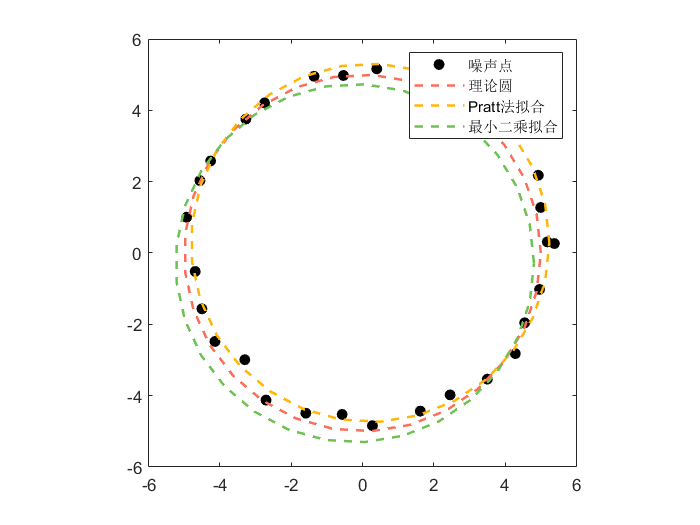

clear;clc;
[all_themes, all_colors] = GetColors();
M = 30;
theta = linspace(0, 2 * pi, M)';
r = 5;
ratio = 0.5;
x1 = r * cos(theta);
y1 = r * sin(theta);
x = x1 + ratio * rand(M, 1);
y = y1 + ratio * rand(M, 1);
xy = [x, y];
% 方式一
par = CircleFitByPratt(xy);
x0 = par(1);
y0 = par(2);
r0 = par(3);
xfit1 = x0 + r0 * cos(theta);
yfit1 = y0 + r0 * sin(theta);
% 方式二
[x0, y0, r0] = CircleFit(x, y);
xfit2 = x0 + r0 * cos(theta);
yfit2 = y0 + r0 * sin(theta);
plot(x, y, 'ok', 'MarkerFaceColor', 'k');
hold on
plot(x1, y1, '--', 'Color', all_colors(1, :), 'LineWidth', 1.5);
plot(xfit1, yfit1, '--', 'Color', all_colors(2, :), 'LineWidth', 1.5);
plot(xfit2, yfit2, '--', 'Color', all_colors(3, :), 'LineWidth', 1.5);
hold off
axis square
legend('噪声点', '理论圆', 'Pratt法拟合', '最小二乘拟合');